Otrais mājasdarbs

Patriks Raiss-Reiss Adaptronika 3. kurss 231REC051

Variants: 753

Basic scenario/map setup

clear all;

scenario = robotScenario(UpdateRate=10);

floorColor = [1 0 0.5];
addMesh(scenario, "Plane", Position=[4.5 2.5 0], Size=[9 5], Color=floorColor);

wallHeight = 1;
wallWidth = 0.05;
wallColor = [1 1 0.8157];

Add outer walls to the map

addMesh(scenario, "Box", Position=[0+wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 5-wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[9-wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 0+wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Add inner walls to the map

addMesh(scenario, "Box", Position=[1, 2, wallHeight/2], ...
    Size=[2, 4, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4, 1.5, wallHeight/2], ...
    Size=[2, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6, 3.5, wallHeight/2], ...
    Size=[4, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6.5, 2, wallHeight/2], ...
    Size=[1, 2, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[7.5, 1.5, wallHeight/2], ...
    Size=[1, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Add obstacles to the map

addMesh(scenario, "Box", Position=[5.8 1.1 0.25], Size=[0.3 0.3 0.3], Color=[0 1 0]);
addMesh(scenario, "Cylinder", Position=[2.4 3.9 0.25], Size=[0.3 0.3], Color=[0 0 1]);

Setup the charging station

addMesh(scenario, "Plane", Position=[8.5 4.5 0.05], Size=[0.6, 0.6], Color=[0 1 0]);

chargeStation = robotPlatform("chargeStation", scenario, InitialBasePosition=[8.5 4.8 0]);
chargeStation.updateMesh("Cuboid", Size=[0.6 0.2 0.2], Color=[0 0.8 0]);

Visualize the map

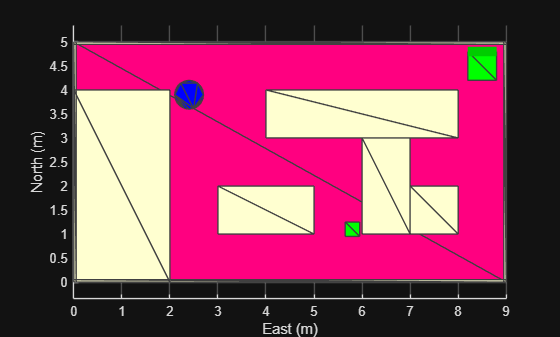

show3D(scenario);
az = 0;
el = 90;
view(az, el);
grid on;

Define and setup the robot

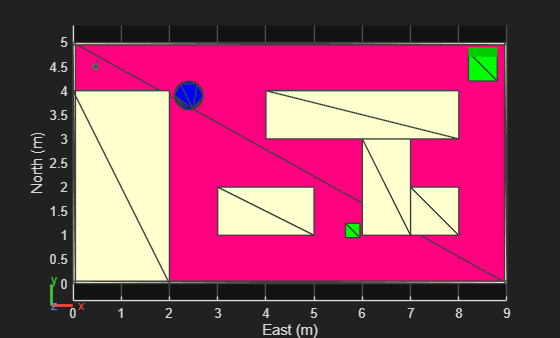

startPosition = [0.5 4.5];
endPosition = [8.5 0.5];
chargePosition = [8.5 4.5];

[pioneerRBT,pioneerRBTInfo] = loadrobot("robotisTurtleBot3Burger");

robot = robotPlatform("MobileRobotA",scenario,...
            RigidBodyTree=pioneerRBT, InitialBasePosition=[startPosition, 0]);

show3D(scenario);
view(az, el);
grid on;

Define and setup the LiDAR sensor

lidarConfig = struct(angleLower=-120, angleUpper=120, angleStep=0.16,...
                      maxRange=0.4, updateRate=2);

lidarmodel = robotLidarPointCloudGenerator(AzimuthResolution=lidarConfig.angleStep,...
                AzimuthLimits=[lidarConfig.angleLower,lidarConfig.angleUpper],...
                ElevationLimits=[0 1], ElevationResolution=1,...
                MaxRange=lidarConfig.maxRange, UpdateRate=lidarConfig.updateRate,...
                HasNoise=false, HasOrganizedOutput=true);

lidar = robotSensor("Lidar", robot, lidarmodel, MountingLocation=[0 0 0.3]);

[ax, plotFrames] = show3D(scenario);
view(az, el);
grid on;

Setup and plan the path for the robot

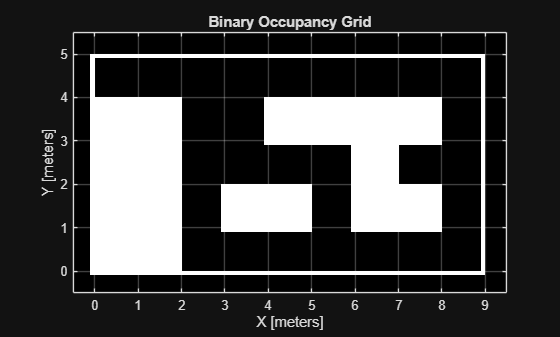

map = binaryOccupancyMap(scenario, GridOriginInLocal=[-0.5 -0.5], MapSize=[10 6], MapHeightLimits=[0 5]);
figure;
show(map);
grid on;

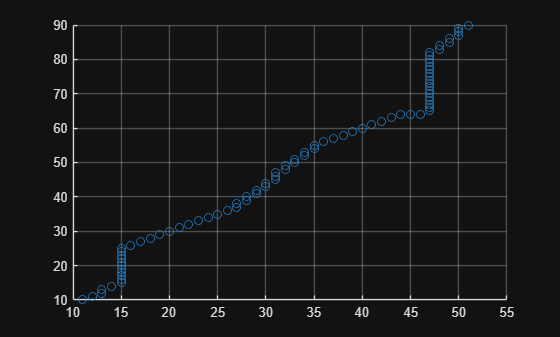

startGridLocation = world2grid(map, startPosition);
endGridLocation = world2grid(map, endPosition);
chargeGridLocation = world2grid(map, chargePosition);

planner = plannerAStarGrid(map);
plannedGridPath = plan(planner, startGridLocation, endGridLocation);
plannedGridPathCharge = plan(planner, endGridLocation, chargeGridLocation);
 
scatter(plannedGridPath(:,1), plannedGridPath(:,2));
grid on;

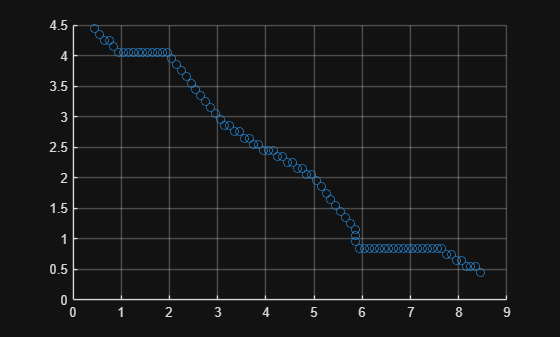

plannedWorldPath = grid2world(map, plannedGridPath);
plannedWorldPathCharge = grid2world(map, plannedGridPathCharge);
scatter(plannedWorldPath(:,1), plannedWorldPath(:,2));
grid on;

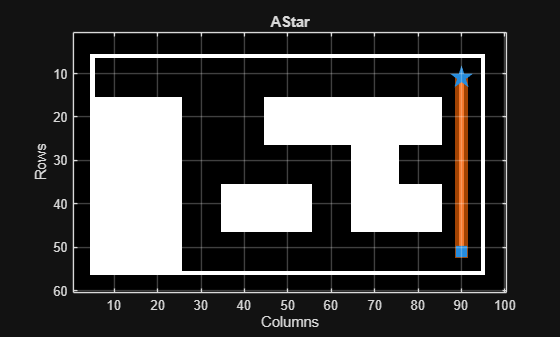

show(planner);
grid on;

Setup the kinematic motion & start and goal poses for the robot

robotDiff = copy(pioneerRBTInfo.MobileBaseMotionModel);
robotDiff.VehicleInputs = "VehicleSpeedHeadingRate";
robotDiff.WheelSpeedRange = [-Inf Inf];

robotStartPosition = plannedWorldPath(1,:);
robotGoalPosition = plannedWorldPath(end,:);
chargeGoalPosition = plannedWorldPathCharge(end,:);
robotInitialOrientation = 0;
robotCurrentPose = [robotStartPosition, robotInitialOrientation]';

Setup the controller for the robot

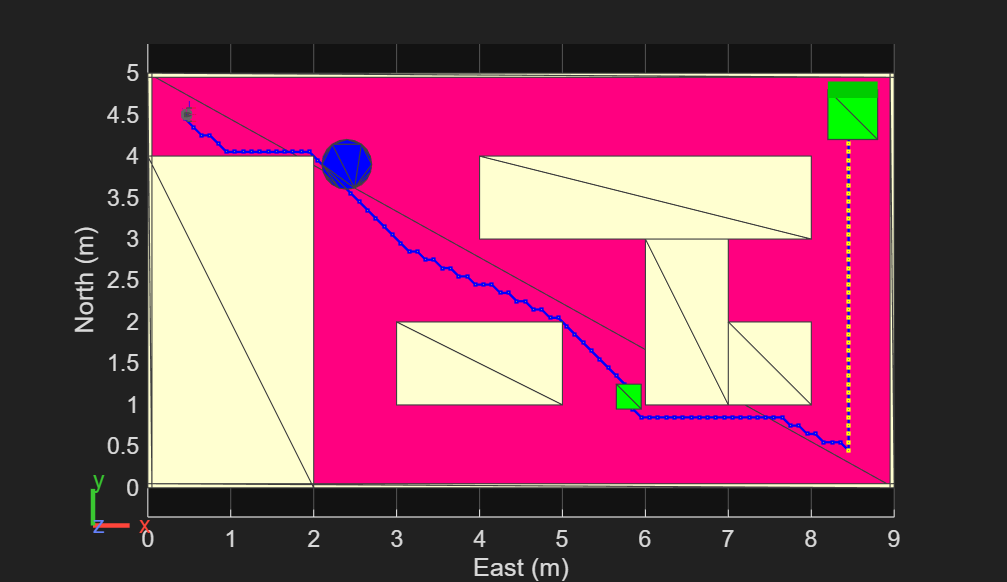

controller = controllerPurePursuit;
controller.Waypoints = plannedWorldPath;
controller.DesiredLinearVelocity = 0.20;
controller.MaxAngularVelocity = 1.7;
controller.LookaheadDistance = 0.3;

vfhA = controllerVFH;
vfhA.UseLidarScan = true;
vfhA.SafetyDistance = 0.1;

hold(ax,"on")

plannedPath = plot(ax,plannedWorldPath(:,1), plannedWorldPath(:,2),"-bs",...
                    LineWidth=1, MarkerSize=1.5, MarkerEdgeColor="b", MarkerFaceColor=[0.5 0.5 0.5]);

plannedPathCharge = plot(ax,plannedWorldPathCharge(:,1), plannedWorldPathCharge(:,2),"-bs",...
                    LineWidth=1, MarkerSize=1.5, MarkerEdgeColor="y", MarkerFaceColor=[0.5 0.5 0.5]);

hold(ax,"off")

Setup and run the simulation

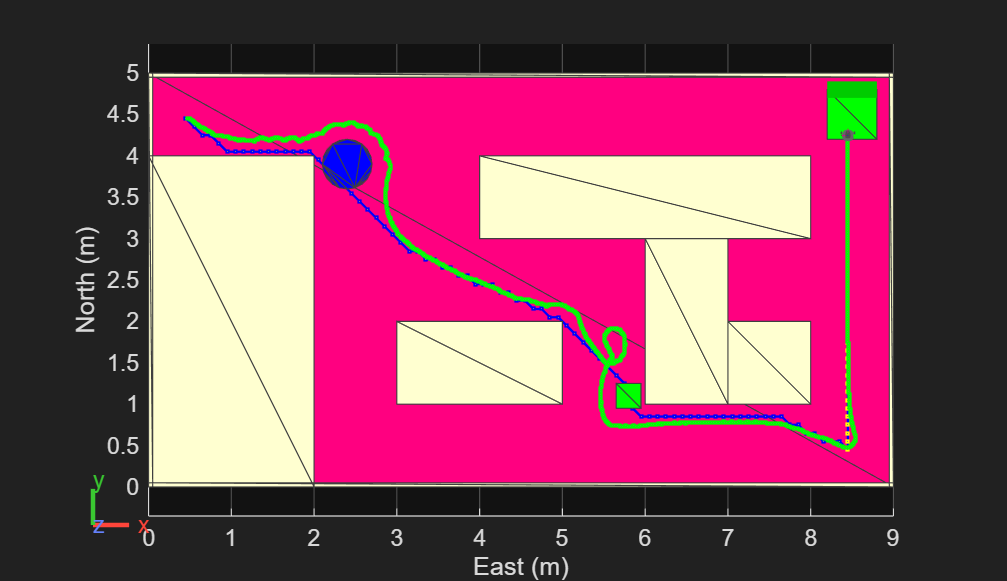

%h = figure;

setup(scenario)

robotReached = false;
robotReachedCharge = false;
stopSimulation = false;

while ~stopSimulation
    
    if ~robotReached
        [robotCurrentPose, isUpdated, robotReached, pointCloudA] = ...
            exampleHelperGetCurrentPose(controller, robotDiff, vfhA, lidar, ...
                    lidarConfig, robotCurrentPose, robotGoalPosition, robotReached);

        if robotReached
            controller.Waypoints = plannedWorldPathCharge;
        end
    end

    if robotReachedCharge
        stopSimulation = true;
    end

    if isUpdated
        show3D(scenario, FastUpdate=true, Parent=ax);
        refreshdata;
        drawnow limitrate;
    end

    if ~robotReached
        move(robot,"base",[robotCurrentPose(1), robotCurrentPose(2), 0, ...
                            zeros(1,6), eul2quat([robotCurrentPose(3), 0,0]), zeros(1,3)]);

        hold(ax,"on");

        followedPath = plot(ax,robotCurrentPose(1),robotCurrentPose(2),"-gs",...
                            LineWidth=1, MarkerSize=1.5, MarkerEdgeColor="g", MarkerFaceColor=[0.5 0.5 0.5]);

        %set(h,'Position',[50 50 800 400])
        %show(vfhA)

        hold(ax,"off");
    end

    if ~robotReachedCharge && robotReached == true
        [robotCurrentPose, isUpdated, robotReachedCharge, pointCloudA] = ...
            exampleHelperGetCurrentPose(controller, robotDiff, vfhA, lidar, ...
                    lidarConfig, robotCurrentPose, chargeGoalPosition, robotReachedCharge);

        move(robot,"base",[robotCurrentPose(1), robotCurrentPose(2), 0, ...
                            zeros(1,6), eul2quat([robotCurrentPose(3), 0,0]), zeros(1,3)]);

        hold(ax,"on");

        followedPathCharge = plot(ax,robotCurrentPose(1),robotCurrentPose(2),"-gs",...
                            LineWidth=1, MarkerSize=1.5, MarkerEdgeColor="g", MarkerFaceColor=[0.5 0.5 0.5]);

        hold(ax,"off");
    end

    advance(scenario);
    updateSensors(scenario);
end